clear;clc;close all
layerfolder='../data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 8.291263 seconds.


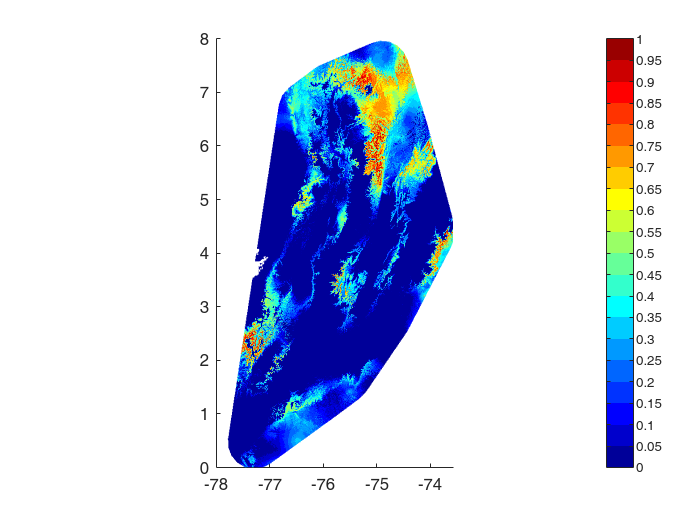

InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

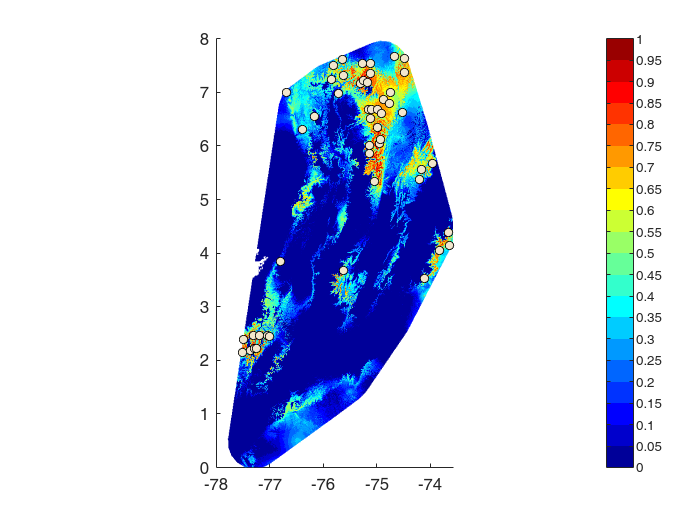

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 50, -3, true, 'GenSP', true, true);

close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, false, false);

----Finding correlation----
Elapsed time is 2.792878 seconds.
----Creating predictors----
¡All done!
Elapsed time is 3.186631 seconds.


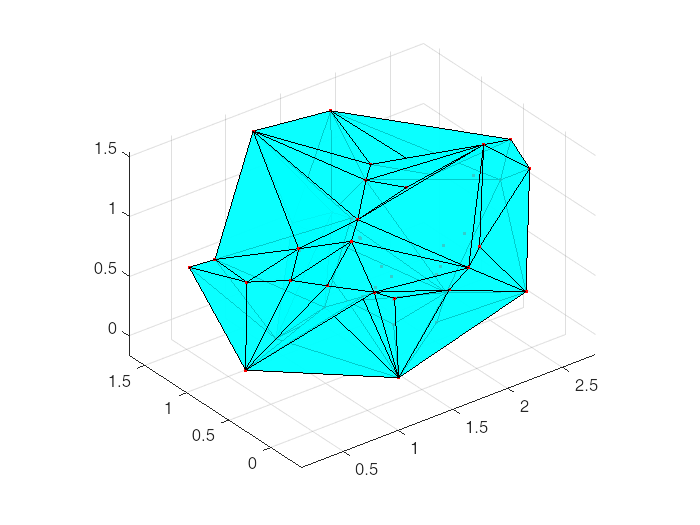

explained =    44.2773
   21.7744
   16.4966
    7.4670
    4.0851
    3.0958
    1.5733
    0.6575
    0.2204
    0.1880


radius =     0.7695    0.9791    0.9351    1.1598    0.9208    0.8778    1.0328    0.8750    0.9101    1.1619    0.9529    1.0760    0.9351
    1.2223    0.6019    1.6752    2.0526    1.6209    1.5560    1.7261    1.6141    1.3537    1.9550    1.7308    1.9320    1.3754
    1.3391    0.7319    1.7266    2.0627    1.6838    1.5062    1.5641    1.4755    1.4289    2.0323    1.7695    1.9634    1.4296
    0.8759    0.1130    1.2581    1.6882    1.2341    1.3014    1.5622    1.4322    1.1392    1.6123    1.4260    1.6347    1.2944
    0.5483    0.8517    1.0534    1.3441    1.0780    1.2376    1.5317    1.4047    1.2050    1.4097    1.2905    1.4548    1.2868
    0.6698    0.8382    1.1212    1.5298    1.1524    1.3312    1.6785    1.5710    1.2963    1.5801    1.4470    1.6454    1.4639
    1.4858    0.9163    1.8811    2.2563    1.8499    1.6561    1.7211    1.6548    1.6285    2.2739    1.9840    2.1975    1.6691
    1.7945    2.3019    1.6429    1.4564    1.5706    1.2082    1.0873    

radiusClass =     0.5483    0.1130    0.4198    0.5192    0.4341    0.5079    0.4682    0.5407    0.1004    0.4672    0.5117    0.5847    0.5272


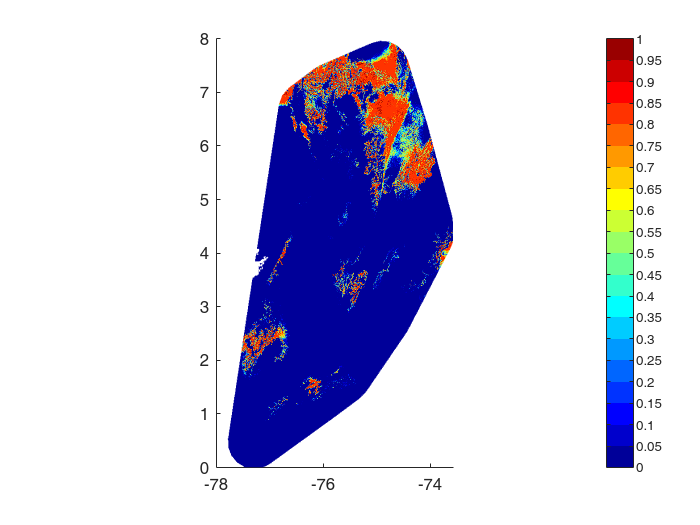

close all, clf
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
class = Coloring(data,show,outlier,outlier2,0.5);

MapMetric(MapInfo.Map,class.map,false)

ans =     0.9069    0.7512


MapMetric(MapInfo.Map,dataf.Map,false)

ans =     0.8261    0.8572


newInfo = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true);
[dataNew,outland] = bnm_prep(newInfo, Dimensions, false, 0.7, false, false);
newPoints(dataNew{1},class)

----Modeling----


ij = 1

-Model 1


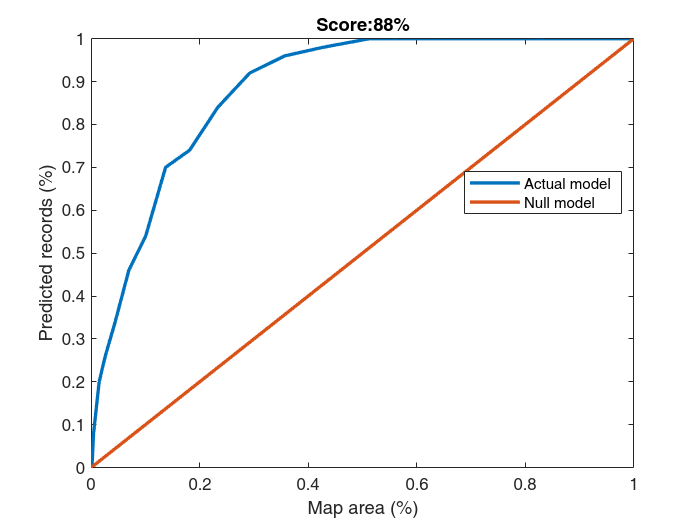

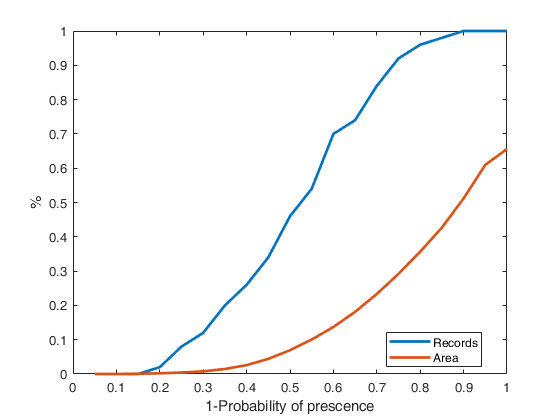

Elapsed time is 2.191928 seconds.


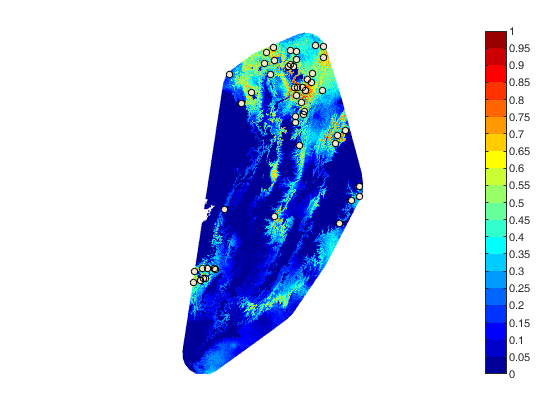

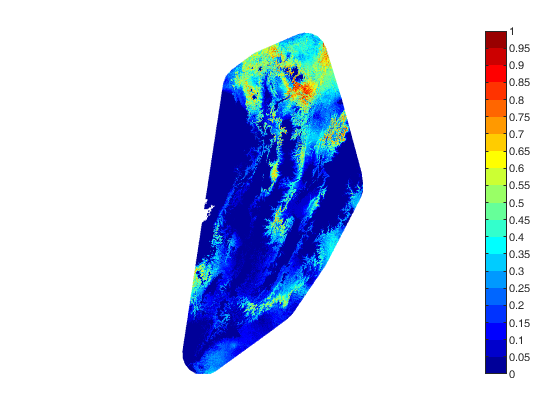

dataf = bnm_modeling(data, '', true, 4, false);

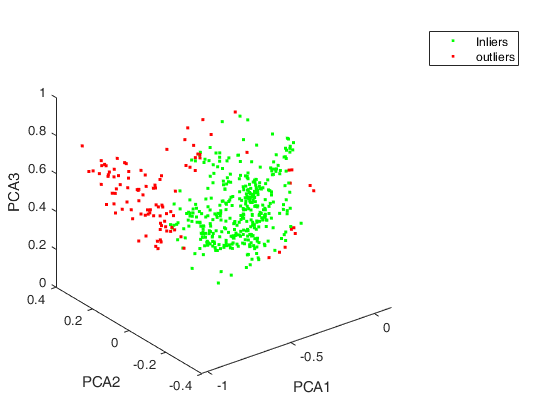

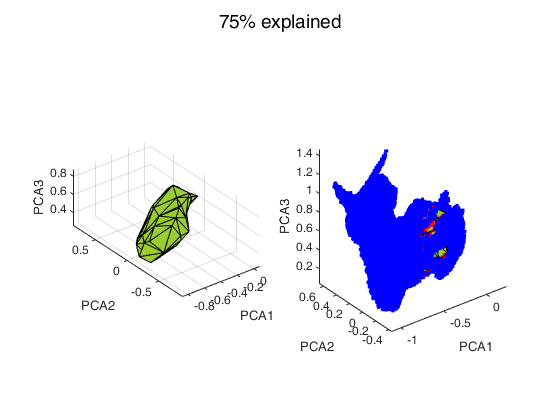

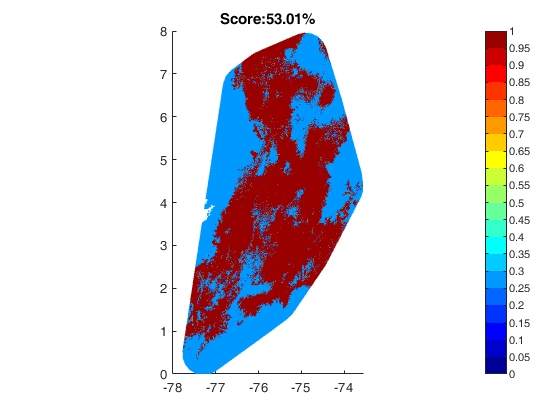

data = struct with fields:
         Tdata: [100×10 table]
    Indicators: [1 4 7 12 13 14]
          Vars: [1 4 7 12]
            T2: [493×22 table]
             Z: [956×507×19 double]
             R: [1×1 map.rasterref.GeographicCellsReference]
        MapPca: [956×507 double]
      ScorePca: 53.0071


close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data{1},show,outlier,outlier2)